kappa_ext = 1.2323e6;
kappa_tot = kappa_ext + .22653e6;
% kerr = 0;
kerr = -.5e5;
detunings = linspace(-30*kappa_tot, 30*kappa_tot, 1000);
omega_0 = 5.7851e9; % in Hz. 
h = 6.626e-34; % just h, not hbar since omega_0 is in Hz
power_input_start_dBm = -60 -81; 
power_input_stop_dBm = -30 -81; % 81dB is approx fridge attenuation. 
power_input_start_watts = 1e-3.*10.^(power_input_start_dBm/10);
power_input_stop_watts = 1e-3.*10.^(power_input_stop_dBm/10);
power_input_in_watts = linspace(power_input_start_watts, power_input_stop_watts, 100);
power_input_in_dBm = 10*log10(power_input_in_watts/1e-3);
power_input_in_numbers = power_input_in_watts/h/omega_0;
kerr = kerr/1e6

kerr = -0.0500

kappa_ext = kappa_ext /1e6;
kappa_tot = kappa_tot/ 1e6;
detunings = detunings/ 1e6;
power_input_in_numbers = power_input_in_numbers/1e6;
[detunings_array, power_input_array] = meshgrid(detunings, power_input_in_numbers);
amp_roots = zeros([size(detunings_array),3]);

for i = 1: size(detunings_array,1)
    for j = 1: size(detunings_array,2)
        amp_roots(i,j,:) = roots([kerr^2, -2*kerr.*detunings_array(i,j), (detunings_array(i,j).^2 + kappa_tot^2 / 4),...
            -kappa_ext * power_input_array(i,j)]);
    end
end

amp_roots(imag(amp_roots) ~=0) = 0;

detunings_array_reps = repmat(detunings_array, [1, 1, 3]);
s11 = ((detunings_array_reps - kerr .* amp_roots) - 1i*(kappa_tot -...
2*kappa_ext)/2)./((detunings_array_reps - kerr .* amp_roots) -1i*kappa_tot/2);
s11(amp_roots == 0) = 5;

% check_detuning_number = randi(length(detunings)/2)
% check_power_input = randi(length(power_input_in_numbers))
check_detuning_number = 394

check_detuning_number = 394

check_power_input = 10

check_power_input = 10

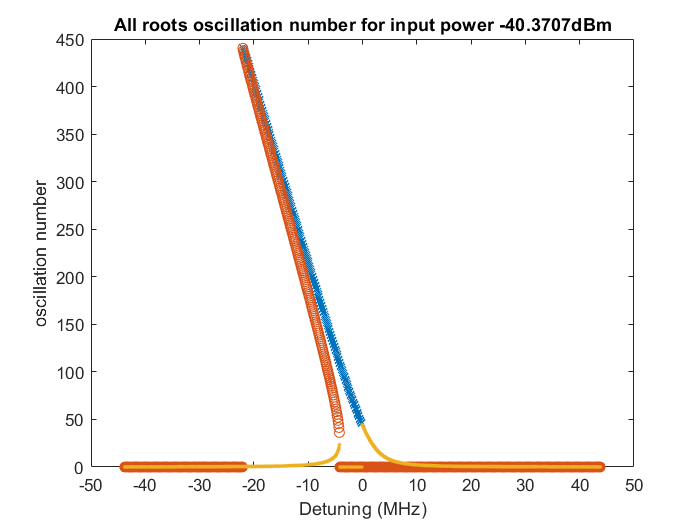

% amp_roots(check_power_input,check_detuning_number,:)
% check_value = kerr^2 .* amp_roots(check_power_input,check_detuning_number,:).^3 - 2*kerr.*detunings_array(check_power_input,check_detuning_number) .* amp_roots(check_power_input,check_detuning_number,:).^2  +...
%     (detunings_array(check_power_input,check_detuning_number)^2 + kappa_tot^2/4) .* amp_roots(check_power_input,check_detuning_number,:) -...
%     kappa_ext * power_input_array(check_power_input,check_detuning_number)
    
% i = randi(100)
% figure
% plot(detunings_array(check_power_input,:), amp_roots(check_power_input,:,1))
% xlabel('Detuning (Hz)')
% ylabel('oscillation number')
% title(['1st root oscillation number for input power ' num2str(power_input_in_dBm(i)) 'dBm'])
% 
% figure
% plot(detunings_array(check_power_input,:), amp_roots(check_power_input,:,2))
% xlabel('Detuning (Hz)')
% ylabel('oscillation number')
% title(['2nd root oscillation number for input power ' num2str(power_input_in_dBm(check_power_input)) 'dBm'])
% 
% figure
% plot(detunings_array(check_power_input,:), amp_roots(check_power_input,:,3))
% xlabel('Detuning (Hz)')
% ylabel('oscillation number')
% title(['3rd root oscillation number for input power ' num2str(power_input_in_dBm(check_power_input)) 'dBm'])

figure
plot(detunings_array(check_power_input,:), amp_roots(check_power_input,:,1),'x')
hold on
plot(detunings_array(check_power_input,:), amp_roots(check_power_input,:,2),'o')
plot(detunings_array(check_power_input,:), amp_roots(check_power_input,:,3),'.')
hold off
xlabel('Detuning (MHz)')
ylabel('oscillation number')
title(['All roots oscillation number for input power ' num2str(power_input_in_dBm(check_power_input) + 81) 'dBm'])

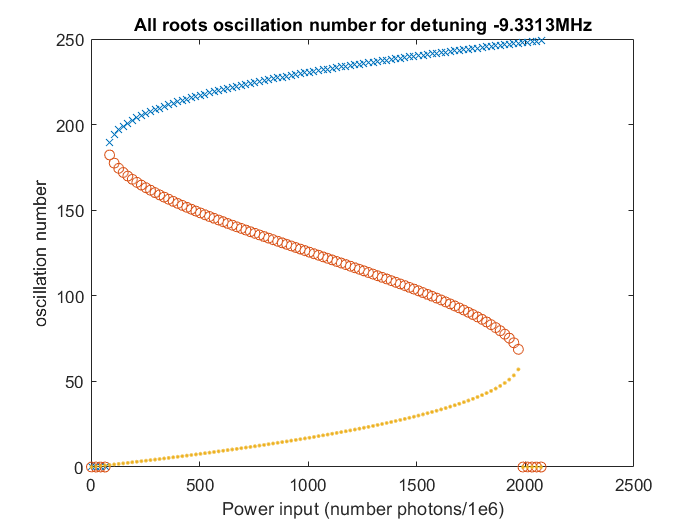


% figure
% plot(power_input_array(:,check_detuning_number), amp_roots(:,check_detuning_number,1))
% xlabel('Power input (number photons)')
% ylabel('oscillation number')
% title(['1st root oscillation number for detuning ' num2str(detunings(check_detuning_number)) 'MHz'])
% 
% figure
% plot(power_input_array(:,check_detuning_number), amp_roots(:,check_detuning_number,2))
% xlabel('Power input (number photons)')
% ylabel('oscillation number')
% title(['2nd root oscillation number for detuning ' num2str(detunings(check_detuning_number)) 'MHz'])
% 
% figure
% plot(power_input_array(:,check_detuning_number), amp_roots(:,check_detuning_number,3))
% xlabel('Power input (number photons)')
% ylabel('oscillation number')
% title(['3rd root oscillation number for detuning ' num2str(detunings(check_detuning_number)) 'MHz'])

figure
plot(power_input_array(:,check_detuning_number), amp_roots(:,check_detuning_number,1),'x')
hold on
plot(power_input_array(:,check_detuning_number), amp_roots(:,check_detuning_number,2),'o')
plot(power_input_array(:,check_detuning_number), amp_roots(:,check_detuning_number,3),'.')
hold off
xlabel('Power input (number photons/1e6)')
ylabel('oscillation number')
title(['All roots oscillation number for detuning ' num2str(detunings(check_detuning_number)) 'MHz'])

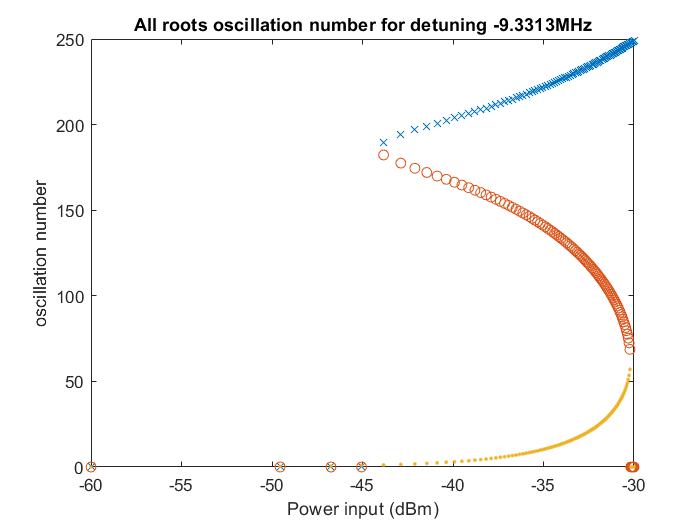


figure
plot(10*log10(power_input_array(:,check_detuning_number)*h*omega_0*1e6/1e-3) + 81, amp_roots(:,check_detuning_number,1),'x')
hold on
plot(10*log10(power_input_array(:,check_detuning_number)*h*omega_0*1e6/1e-3) + 81, amp_roots(:,check_detuning_number,2),'o')
plot(10*log10(power_input_array(:,check_detuning_number)*h*omega_0*1e6/1e-3) + 81, amp_roots(:,check_detuning_number,3),'.')
hold off
xlabel('Power input (dBm)')
ylabel('oscillation number')
title(['All roots oscillation number for detuning ' num2str(detunings(check_detuning_number)) 'MHz'])

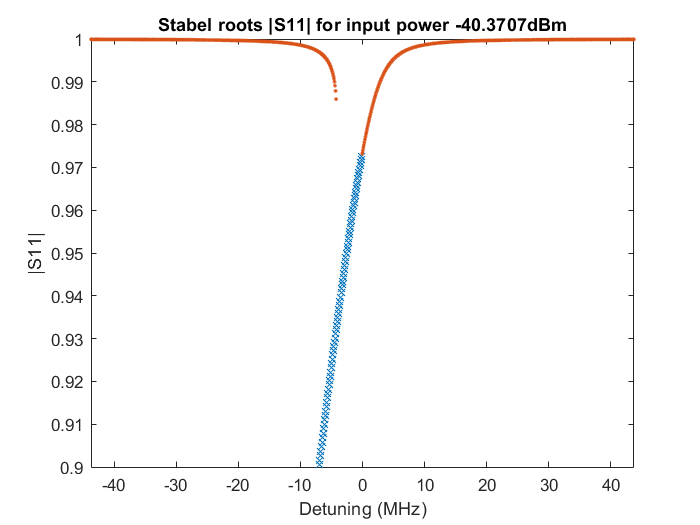


figure
plot(detunings_array(check_power_input,:), abs(s11(check_power_input,:,1)),'x')
hold on
% plot(detunings_array(check_power_input,:), abs(s11(check_power_input,:,2)),'o')
plot(detunings_array(check_power_input,:), abs(s11(check_power_input,:,3)),'.')
hold off
xlabel('Detuning (MHz)')
ylabel('|S11|')
axis([detunings(1) detunings(end) .9 1])
title(['Stabel roots |S11| for input power ' num2str(power_input_in_dBm(check_power_input) + 81) 'dBm'])

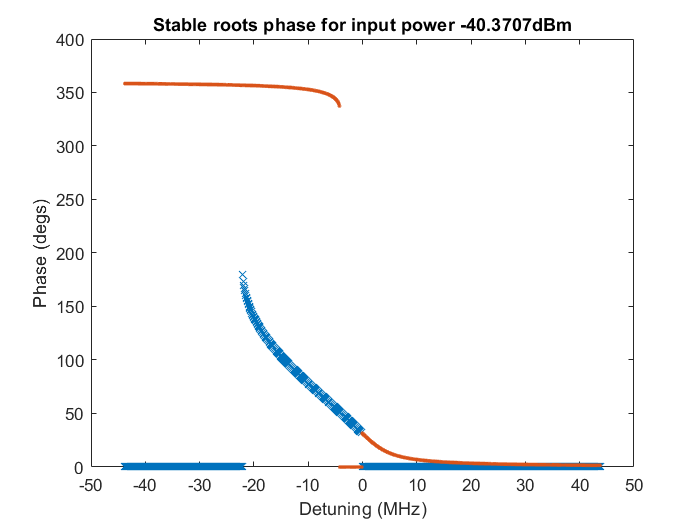


figure
plot(detunings_array(check_power_input,:), wrapTo360(angle(s11(check_power_input,:,1))*180/pi),'x')
hold on
% plot(detunings_array(check_power_input,:), angle(s11(check_power_input,:,2))*180/pi,'o')
plot(detunings_array(check_power_input,:), wrapTo360(angle(s11(check_power_input,:,3))*180/pi),'.')
hold off
xlabel('Detuning (MHz)')
ylabel('Phase (degs)')
title(['Stable roots phase for input power ' num2str(power_input_in_dBm(check_power_input) + 81) 'dBm'])

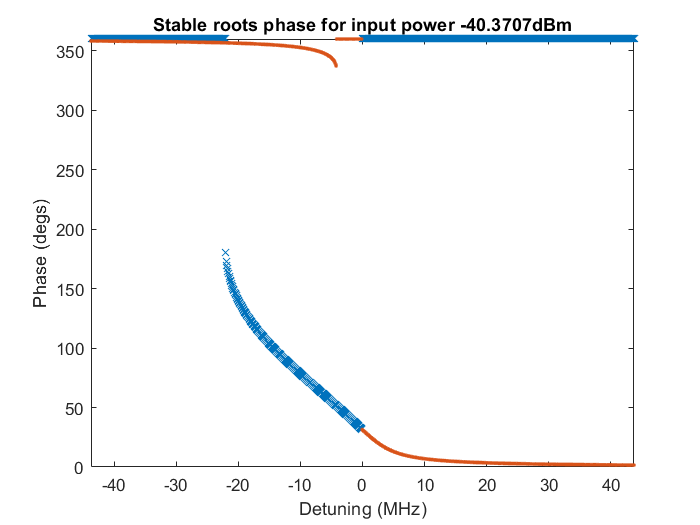


s11_phase = angle(s11(check_power_input,:,:))*180/pi;
s11_phase(s11_phase==0) = 720;
s11_phase = wrapTo360(s11_phase);
figure
plot(detunings_array(check_power_input,:), s11_phase(1,:,1),'x')
hold on
% plot(detunings_array(check_power_input,:), angle(s11(check_power_input,:,2))*180/pi,'o')
plot(detunings_array(check_power_input,:),s11_phase(1,:,3) ,'.')
hold off
xlabel('Detuning (MHz)')
ylabel('Phase (degs)')
axis([detunings(1) detunings(end) 0 360])
title(['Stable roots phase for input power ' num2str(power_input_in_dBm(check_power_input) + 81) 'dBm'])